% Load training data
folderPath = 'C:\Users\eshil\Desktop\pythonpytorch\ShapeDataset\archive\shapes';
imageSize = [28, 28];

% List the subfolders in the main folder
subfolders = dir(folderPath);
subfolders = subfolders([subfolders.isdir]); % Select only directories
subfolders = subfolders(~ismember({subfolders.name}, {'.', '..'})); % Exclude '.' and '..'

% Initialize variables
images = [];
labels = cell(0, 1);

% Loop over the subfolders
for i = 1:numel(subfolders)
    subfolder = subfolders(i).name;
    label = subfolder; % Assign the folder name as the label

    % Read the PNG images from the subfolder
    filePattern = fullfile(folderPath, subfolder, '*.png');
    imageFiles = dir(filePattern);

    % Loop over the image files in the subfolder
    for j = 1:numel(imageFiles)
        imagePath = fullfile(folderPath, subfolder, imageFiles(j).name);
        image = imread(imagePath);

        % Resize the image to the desired size
        image = imresize(image, imageSize);

        % Normalize the pixel values to [0, 1]
        image = double(image) / 255;

        % Convert to greyscale
        image = rgb2gray(image);

        % Append the image and label to the lists
        images = cat(4, images, image);
        labels{end+1} = label;
    end
end
% Convert labels to categorical
labels = categorical(labels);

% Shuffle the images and labels
shuffledIndices = randperm(numel(labels));
images = images(:, :, :, shuffledIndices);
labels = labels(shuffledIndices);

% Split the data into training and testing sets
trainRatio = 0.8; % Ratio of training set size to the total data size
numTrain = round(trainRatio * numel(labels));
trainImages = images(:, :, :, 1:numTrain);
trainLabels = labels(1:numTrain);
testImages = images(:, :, :, numTrain+1:end);
testLabels = labels(numTrain+1:end);
layers = [
    imageInputLayer([28 28 1]) % Input layer for resized images
    convolution2dLayer(3, 32, 'Padding', 'same')
    reluLayer()
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 64, 'Padding', 'same')
    reluLayer()
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(64)
    reluLayer()
    fullyConnectedLayer(3) % Output layer with 3 classes
    softmaxLayer()
    classificationLayer()
];

% Parameters
learningRate = 0.001;
numTrainBatches = 4;
numEpochs = 4;
optimizer = 'adam';
lossFunction = 'crossentropy';

% Define the training options
options = trainingOptions(optimizer, ...
    'InitialLearnRate', learningRate, ...
    'MaxEpochs', numEpochs, ...
    'MiniBatchSize', numTrainBatches, ...
    'Plots', 'training-progress', ...
    'Verbose', true);

% Train the model
net = trainNetwork(trainImages, trainLabels, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       25.00% |       1.1115 |          0.0010 |
|       1 |          50 |       00:00:09 |      100.00% |       0.8904 |          0.0010 |
|       2 |         100 |       00:00:10 |      100.00% |       0.7101 |          0.0010 |
|       3 |         150 |       00:00:11 |       75.00% |       0.7890 |          0.0010 |
|       4 |         200 |       00:00:11 |       75.00% |       0.7184 |          0.0010 |
|       4 |         240 |       00:00:12 |      100.00% |       0.0123 |          0.0010 |
|==========================


% Test the model
testPredictions = classify(net, testImages);
testAccuracy = mean(testPredictions == testLabels') * 100;

% Display test accuracy
fprintf('Test Accuracy: %.2f%%\n', testAccuracy);

Test Accuracy: 80.00%



save('saved_network.mat', 'net');

x = [454 454 452 452 452 450 450 450 448 448 448 446 446 446 444 444 444 444 442 442 442 440 440 440 438 438 438 438 436 436 436 436 434 434 434 434 434 434 432 432 432 432 432 432 432 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 428 428 428 428 428 430 432 434 436 436 438 440 442 444 446 448 450 452 454 456 458 460 462 464 466 468 470 472 472 474 476 478 480 482 484 486 488 490 492 492 494 496 498 500 502 504 506 508 510 512 514 516 518 520 522 524 526 528 530 532 534 536 538 540 542 544 546 548 550 552 554 556 558 560 562 564 566 568 570 572 574 576 576 578 578 578 580 580 580 582 582 582 582 582 584 584 584 584 584 586 586 586 586 586 586 586 586 588 588 588 588 588 588 588 588 588 588 590 590 590 590 590 590 590 590 590 590 590 592 592 592 592 592 592 592 594 594 594 594 594 594 594 596 596 596 596 596 598 598 598 598 598 598 600 600 600 600 600 602 602 602 602 602 604 604 604 604 604 604 604 602 602 600 598 596 594 592 590 588 586 584 582 580 578 576 574 572 570 568 566 564 562 560 558 556 554 552 550 548 546 544 542 540 538 536 534 532 530 528 526 524 522 520 518 516 514 512 510 508 506 504 502 502 500 498 496 494 492 490 488 488 486 484 482 480 478 478 476 474 472 470 468 466 464 462 460 458 456 454 454 454 454 454 454 454 454 454 452 452 452];
y = [220 222 224 226 228 228 230 232 232 234 236 236 238 240 242 244 246 248 248 250 252 254 256 258 260 262 264 266 266 268 270 272 274 276 278 280 282 284 284 286 288 290 292 294 296 296 298 300 302 304 306 308 310 312 314 316 318 320 322 324 326 328 330 332 334 336 338 340 342 342 344 346 348 350 350 350 350 350 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 354 354 354 354 354 354 354 354 354 354 354 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 356 356 354 352 350 348 346 346 344 342 340 338 338 336 334 332 330 330 328 326 324 322 320 318 316 316 314 312 310 308 306 304 302 300 298 298 296 294 292 290 288 286 284 282 280 278 278 276 274 272 270 268 266 266 264 262 260 258 256 254 254 252 250 248 246 246 244 242 240 238 236 236 234 232 230 228 228 226 224 222 220 220 218 216 214 212 210 208 208 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 204 204 204 204 204 204 204 204 202 202 202 202 202 202 200 200 200 200 200 200 200 200 200 200 200 200 200 202 204 206 208 210 212 214 216 216 218 220];
    
    maxX = max(x);
    maxY = max(y);
    minX = min(x);
    minY = min(y);
    width = maxX - minX + 1;
    height = maxY - minY + 1;
    
    % Create an empty image
    image = zeros(height, width);
    
    % Convert the coordinates to image pixels
    pixelX = x - minX + 1;
    pixelY = y - minY + 1;
    
    % Set the corresponding pixels in the image to black
    for i = 1:numel(x)
        image(pixelY(i), pixelX(i)) = 1;
    end
    disp("Constructed image")

Constructed image


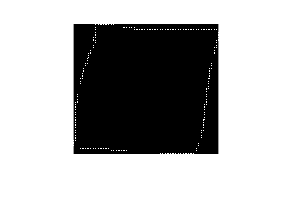

    imshow(image)

    %% Dilation operation
    % using dilation, we can thicken the line of the shape
    % scale_ratio deals with different sized images, since the input
    % for the strel function is a fixed amount of pixels
    scale_ratio = fix(0.02 * max(width, height));

    se = strel('disk', scale_ratio); 

    dilImage = imdilate(image, se);
    
    disp("Dilated image")

Dilated image


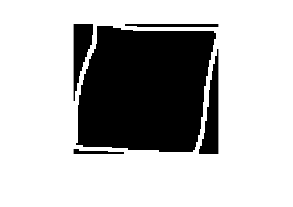

    imshow(dilImage)

    % inverse the color
    image = ~dilImage;
    disp("Colors inversed")

Colors inversed


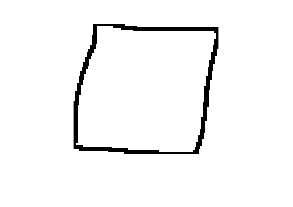

    imshow(image)

    %% Resize the image to the specified size using bilinear interpolation
    image = imresize(image,[28,28], 'bilinear');
    image = double(image);
    %% Prediction

x = [454 454 452 452 452 450 450 450 448 448 448 446 446 446 444 444 444 444 442 442 442 440 440 440 438 438 438 438 436 436 436 436 434 434 434 434 434 434 432 432 432 432 432 432 432 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 430 428 428 428 428 428 430 432 434 436 436 438 440 442 444 446 448 450 452 454 456 458 460 462 464 466 468 470 472 472 474 476 478 480 482 484 486 488 490 492 492 494 496 498 500 502 504 506 508 510 512 514 516 518 520 522 524 526 528 530 532 534 536 538 540 542 544 546 548 550 552 554 556 558 560 562 564 566 568 570 572 574 576 576 578 578 578 580 580 580 582 582 582 582 582 584 584 584 584 584 586 586 586 586 586 586 586 586 588 588 588 588 588 588 588 588 588 588 590 590 590 590 590 590 590 590 590 590 590 592 592 592 592 592 592 592 594 594 594 594 594 594 594 596 596 596 596 596 598 598 598 598 598 598 600 600 600 600 600 602 602 602 602 602 604 604 604 604 604 604 604 602 602 600 598 596 594 592 590 588 586 584 582 580 578 576 574 572 570 568 566 564 562 560 558 556 554 552 550 548 546 544 542 540 538 536 534 532 530 528 526 524 522 520 518 516 514 512 510 508 506 504 502 502 500 498 496 494 492 490 488 488 486 484 482 480 478 478 476 474 472 470 468 466 464 462 460 458 456 454 454 454 454 454 454 454 454 454 452 452 452];
y = [220 222 224 226 228 228 230 232 232 234 236 236 238 240 242 244 246 248 248 250 252 254 256 258 260 262 264 266 266 268 270 272 274 276 278 280 282 284 284 286 288 290 292 294 296 296 298 300 302 304 306 308 310 312 314 316 318 320 322 324 326 328 330 332 334 336 338 340 342 342 344 346 348 350 350 350 350 350 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 352 354 354 354 354 354 354 354 354 354 354 354 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 356 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 358 356 356 354 352 350 348 346 346 344 342 340 338 338 336 334 332 330 330 328 326 324 322 320 318 316 316 314 312 310 308 306 304 302 300 298 298 296 294 292 290 288 286 284 282 280 278 278 276 274 272 270 268 266 266 264 262 260 258 256 254 254 252 250 248 246 246 244 242 240 238 236 236 234 232 230 228 228 226 224 222 220 220 218 216 214 212 210 208 208 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 206 204 204 204 204 204 204 204 204 202 202 202 202 202 202 200 200 200 200 200 200 200 200 200 200 200 200 200 202 204 206 208 210 212 214 216 216 218 220];
predictNet(x,y)

ans = 1